clearvars; close all;
addpath(genpath('./functions'));

input_data_path = './input_data/';

if ~exist(input_data_path, "dir")
    mkdir(input_data_path)
end

dzm = 3.75;
bgbins = 100;
td = 280;
n_avg = 10;
sib_hkm = 12; % the begining range for sib correction fitting curve

file_date_dt = datetime("2022-09-23", "InputFormat", "uuuu-MM-dd"); 
file_date = string(datetime(file_date_dt, "Format","uuuuMMdd"));
folder_path = strcat(input_data_path, file_date, '/txt/');
save_path = strcat('./results/', file_date,'/');
[st,f] = mkdir(save_path);

Read raw data from files

fds = fileDatastore(folder_path, 'ReadFcn', @importdata,'FileExtensions',{'.txt'});
fullFileNames = fds.Files;
num_files = length(fullFileNames);

times = NaT(1,num_files);

preview_data = preview(fds);
dimension = size(preview_data.data);
raw_data = NaN(dimension(1), dimension(2), num_files);
n_bin = dimension(1);
n_channels = dimension(2);

fr_channels = [1 2 3 4];
nr_channels = [5 6 7 8];
an_channels = [1 3 5 7];
pc_channels = [2 4 6 8];

height = dzm.*(1:1:n_bin)';
hkm = height./1000;

for i = 1:num_files
    Data=read(fds);

    raw_data(:,:,i) = Data.data;

    temp_str = cell2mat(Data.textdata(2,1));
    infmt ='dd/MM/yyyy HH:mm:ss';
    times(i) = datetime(temp_str(10:28),'InputFormat',infmt);
end

Time average data

raw_timetable = array2timetable(reshape(permute(raw_data,[3 2 1]), [num_files n_bin*dimension(2)]),'RowTimes',times);
raw_timetable_retimed = retime(raw_timetable,'regular','mean','TimeStep',minutes(n_avg));
raw_data_avg = table2array(raw_timetable_retimed);
raw_data_avg = reshape(raw_data_avg, [], dimension(2), n_bin);
raw_data_avg = permute(raw_data_avg, [3 2 1]);

raw_data_avg(:,:,[1,end]) = []; % remove later 

times_avg = raw_timetable_retimed.Time;
times_avg([1,end]) = []; % remove later

n_profiles = length(times_avg);

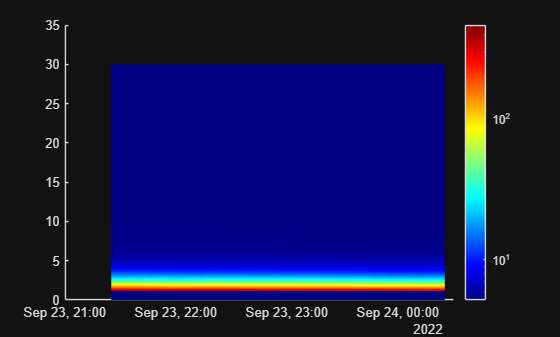

% Find location of gate using max value of analog signal
[~,max_signal_locations] = max(raw_data_avg,[],1);
max_signal_locations = squeeze(max_signal_locations);
max_signal_locations = max_signal_locations(an_channels,:);
gate_bin_fr = max(max_signal_locations([1 2],:));
gate_bin_nr = max(max_signal_locations([3 4],:));

raw_data_avg_gate = raw_data_avg;
for i = 1:n_profiles
    raw_data_avg_gate(1:gate_bin_fr(i),fr_channels,i) = NaN;
    raw_data_avg_gate(1:gate_bin_nr(i),nr_channels,i) = NaN;
end

tmp_plot = squeeze(raw_data_avg_gate(:,1,:));
figure;
hold on
I = imagesc(times_avg,hkm,tmp_plot);
hold off
% ylim([0 1])
colorbar
colormap('jet')
set(gca,'YDir','Normal')
set(gca,'ColorScale','log')

id = 10;
% profile_plot(id,raw_data_avg, hkm, times_avg, "Time-Averaged Analog Signals","Time-Averaged Photon-Counting Signals")

Perform dead time correction on time average photon-counting signals

data_pc_corr = raw_data_avg_gate;
data_pc_corr(:,pc_channels,:) = data_pc_corr(:,pc_channels,:)./(1-data_pc_corr(:,pc_channels,:)/td);

% profile_plot(id,data_pc_corr, hkm, times_avg, "Time-Averaged Analog Signals","Time-Averaged Dead-Time Corrected Photon-Counting Signals")

Calculate and subtract background from each profile

bg_ind = n_bin-bgbins:n_bin;
solar_background = NaN(n_channels,n_profiles);

solar_background =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


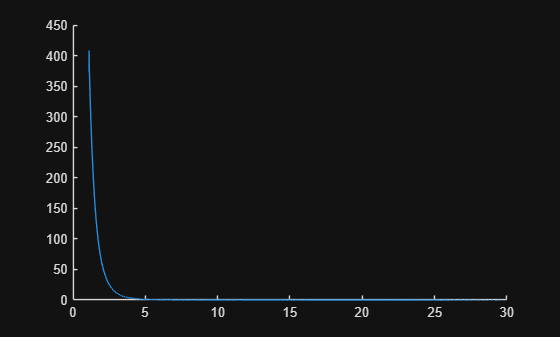


data_pc_bg = data_pc_corr;
for i = 1:n_profiles
    for j = 1:n_channels
        bg = mean(data_pc_corr(bg_ind,j,i));
        solar_background(j,i) = bg;
        
        data_pc_bg(:,j,i) = data_pc_bg(:,j,i) - bg; 
        data_pc_bg(data_pc_bg(:,j,i)<0,j,i) = NaN;
    end
end

tmp_plot = squeeze(data_pc_bg(:,1,:));
negatives = find(tmp_plot(:,id)<0);
figure;
hold on
plot(hkm,tmp_plot(:,id))
scatter(hkm(negatives),tmp_plot(negatives,id))
hold off

Calculate and subtract SIB from 287 nm PC and Analog profiles before background subtraction

sib_id = hkm > sib_hkm;

data_pc_sib = NaN(size(data_pc_corr));
fits = cell(n_channels,n_profiles);
for i = 1:n_profiles
    for j = 1:n_channels
        f = fit(hkm(sib_id), squeeze(data_pc_corr(sib_id,j,i)),'exp1');

        fits{j,i} = f;
        data_pc_sib(:,j,i) = data_pc_bg(:,j,i) - f(hkm); % not sure if it should be subtracted from bg corrected or not
    end
end

channel = 2;
f_test = fits{channel,id};

Plot of PC 287 nm channel after each stage of pre-processing and SIB fit curve

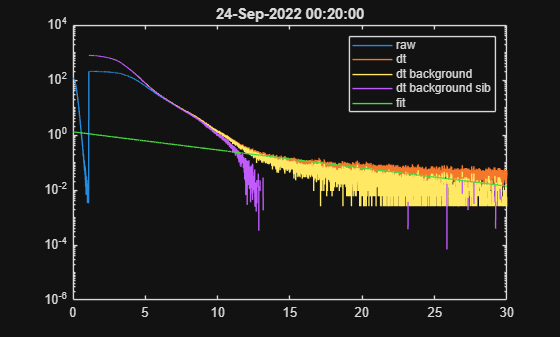

shw_plt = true;
if shw_plt == true
    figure;
    semilogy(hkm, raw_data_avg(:,channel,id),...
             hkm, data_pc_corr(:,channel,id),...
             hkm, data_pc_bg(:,channel,id),...
             hkm, data_pc_sib(:,channel,id),...
             hkm, f_test(hkm))
    
    ylim([10^-6 10^4])
    legend(["raw" "dt" "dt background" "dt background sib", "fit"])
    title(string(times_avg(id)))
end

Plots of pre-processed photon counting and analog signals for each detector

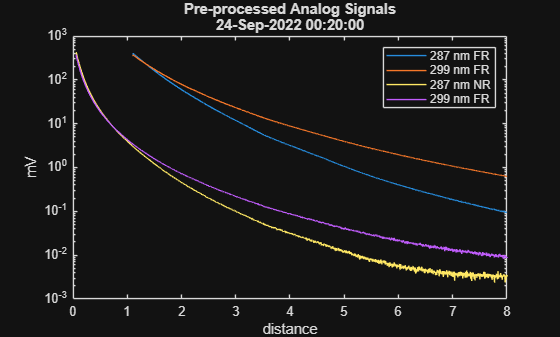

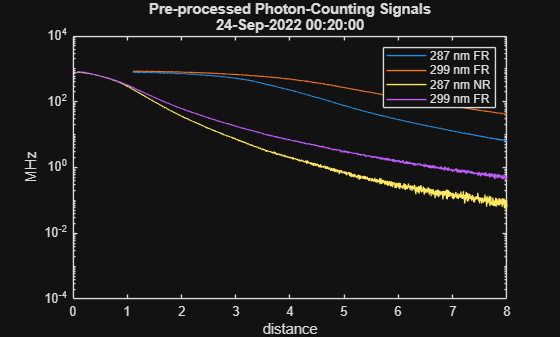

shw_plt = true;
if shw_plt == true
    profile_plot(id,data_pc_bg, hkm, times_avg, "Pre-processed Analog Signals","Pre-processed Photon-Counting Signals")
end

Determine location of clouds

tpos = .012;
tneg = .012;
cld_search = 100;

p_z2 = data_pc_bg.*hkm.^2;
ln_p_z2 = log(p_z2);
dp_z2 = NaN(size(p_z2));
dlnp_z2 = NaN(size(p_z2));

cld_mask = zeros(size(p_z2));

[~,g_cld] = sgolay(2,11);

for i = 1:n_profiles
    for j = 1:n_channels
        dp_z2(:,j,i) = conv(p_z2(:,j,i), -1.*g_cld(:,2),'same');
        dlnp_z2(:,j,i) = conv(ln_p_z2(:,j,i), -1.*g_cld(:,2),'same');
    end
end

dp_z2 = movmean(dp_z2, 45);
dlnp_z2 = movmean(dlnp_z2, 45);

start_bin = 1000;
end_bin = 4000;
for i = 1:n_profiles
    for j = 1:n_channels

        for k = start_bin:min(n_bin-cld_search,end_bin)
            if dlnp_z2(k,j,i) >= tpos
                for l = k:k+cld_search
                    if dlnp_z2(l,j,i) <= tneg
                        cld_mask(k:l,j,i) = 1;
                    end
                end
            end
        end

    end
end

Plot of P(z)*z^2 for analog 299 nm

shw_plt = false;
if shw_plt == true
    figure
    semilogx(p_z2(:,3,id),hkm)
    xlim([1 100])
    ylim([0 12])
    ylabel('km')
end

Plot of derivative of ln(P(z))*z^2 for analog 299 nm

shw_plt = false;
if shw_plt == true
    figure
    hold on;
    plot(dlnp_z2(:,3,id),hkm)
    ylim([0 10])
    xlim([-.06 .04])
end

Plot showing cloud mask

shw_plt = false;
if shw_plt == true
    figure;
    imagesc(times_avg,hkm,squeeze(cld_mask(:,1,:)))
    set(gca,'YDir','normal');
    colorbar;
    colormap('gray')
    ylim([0 10])
    ylabel('km')
end

Calculate initial SNR of PC channels

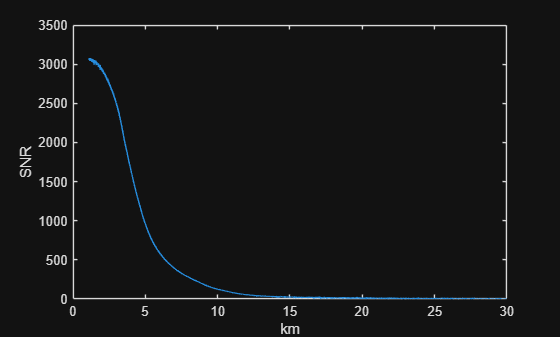

n_factor = sqrt(n_avg*1200);

solar_bg_full = repmat(reshape(solar_background(pc_channels,:),1,length(pc_channels),n_profiles),n_bin,1,1);
SNR_initial = n_factor .* data_pc_bg(:,pc_channels,:) ./ sqrt(data_pc_bg(:,pc_channels,:) + solar_bg_full);

figure;
plot(hkm,SNR_initial(:,1,id))
xlabel('km')
ylabel('SNR')

Glue Photon-counting and analog signals where there are no clouds

min_toggle = 0.5; % need to check this
max_toggle = 10; % also this

an_data = data_pc_bg(:,an_channels,:);
pc_data = data_pc_bg(:,pc_channels,:);

pc_glue_valid = false(size(pc_data));
pc_glue_valid(pc_data > min_toggle & pc_data < max_toggle & ~isnan(an_data) & ~isnan(pc_data)) = true;
pc_glue_valid(hkm < 2 | hkm > 30,[1 2],:) = false; % change this to be based off of gate opening time and SNR
pc_glue_valid(hkm < 0.05 | hkm > 30,[3 4],:) = false; % also add check for clouds

Plots that show valid PC-Analog gluing regions for each detector

shw_plt = false;
if shw_plt == true
    figure;
    imagesc(times_avg,hkm,double(squeeze(pc_glue_valid(:,1,:))))
    colormap('gray')
    set(gca, 'YDir','normal')
    ylabel('km')
    ylim([0 15])
    title('287 nm FR valid merge')
    figure;
    imagesc(times_avg,hkm,double(squeeze(pc_glue_valid(:,2,:))))
    colormap('gray')
    set(gca, 'YDir','normal')
    ylabel('km')
    ylim([0 15])
    title('299 nm FR valid merge')
    figure;
    imagesc(times_avg,hkm,double(squeeze(pc_glue_valid(:,3,:))))
    colormap('gray')
    set(gca, 'YDir','normal')
    ylabel('km')
    ylim([0 15])
    title('287 nm NR valid merge')
    figure;
    imagesc(times_avg,hkm,double(squeeze(pc_glue_valid(:,4,:))))
    colormap('gray')
    set(gca, 'YDir','normal')
    ylabel('km')
    ylim([0 15])
    title('299 nm NR valid merge')
end
pc_glue_287_fr = find(pc_glue_valid(:,1,id));
pc_glue_299_fr = find(pc_glue_valid(:,2,id));
pc_glue_287_nr = find(pc_glue_valid(:,3,id));
pc_glue_299_nr = find(pc_glue_valid(:,4,id));

Plots that show highlight valid gluing points in signals from each channel

shw_plt = false;
if shw_plt == true
    figure;
    semilogy(hkm,pc_data(:,1,id));
    hold on;
    plot(hkm,pc_data(:,2,id));
    scatter(hkm(pc_glue_287_fr),pc_data(pc_glue_287_fr,1,id))
    scatter(hkm(pc_glue_299_fr),pc_data(pc_glue_299_fr,2,id))
    yline(min_toggle, '--')
    yline(max_toggle, '--')
    hold off
    xlabel('km')
    ylabel('MHz')
    xlim([0 15])
    title('Photon Counting FR')
    legend(["287 nm" "299 nm" "287 valid merge" "299 valid merge"])
    figure;
    semilogy(hkm,an_data(:,1,id));
    hold on;
    plot(hkm,an_data(:,2,id));
    scatter(hkm(pc_glue_287_fr),an_data(pc_glue_287_fr,1,id))
    scatter(hkm(pc_glue_299_fr),an_data(pc_glue_299_fr,2,id))
    hold off
    xlabel('km')
    xlim([0 15])
    title('Analog FR')
    legend(["287 nm" "299 nm" "287 valid merge" "299 valid merge"])
    figure;
    semilogy(hkm,pc_data(:,3,id));
    hold on;
    plot(hkm,pc_data(:,4,id));
    scatter(hkm(pc_glue_287_nr),pc_data(pc_glue_287_nr,3,id))
    scatter(hkm(pc_glue_299_nr),pc_data(pc_glue_299_nr,4,id))
    yline(min_toggle, '--')
    yline(max_toggle, '--')
    hold off
    xlabel('km')
    ylabel('MHz')
    xlim([0 5])
    title('Photon Counting NR')
    legend(["287 nm" "299 nm" "287 valid merge" "299 valid merge"])
    figure;
    semilogy(hkm,an_data(:,3,id));
    hold on;
    plot(hkm,an_data(:,4,id));
    scatter(hkm(pc_glue_287_nr),an_data(pc_glue_287_nr,3,id))
    scatter(hkm(pc_glue_299_nr),an_data(pc_glue_299_nr,4,id))
    hold off
    xlabel('km')
    xlim([0 5])
    title('Analog NR')
    legend(["287 nm" "299 nm" "287 valid merge" "299 valid merge"])
end

data_glued = data_pc_bg(:,pc_channels,:);
scaling_coeffs = NaN(2,length(an_channels),n_profiles);

% add check for linearity in AN-PC relationship in this range
for i = 1:n_profiles
    for j = 1:n_channels/2
        an_temp = an_data(:,j,i);
        pc_temp = pc_data(:,j,i);

        valid_id = find(pc_glue_valid(:,j,i));
        b = scale_analog(an_temp(valid_id), pc_temp(valid_id));
        scaling_coeffs(:,j,i) = b;

        an_scaled_temp = an_temp.*b(2) + b(1);
        data_glued(pc_temp > max_toggle,j,i) = an_scaled_temp(pc_temp > max_toggle);
    end
end

Plots that show regression results from each detector

shw_plt = false;
if shw_plt == true
    figure;
    hold on
    scatter(an_data(pc_glue_287_fr,1,id),pc_data(pc_glue_287_fr,1,id))
    plot(an_data(pc_glue_287_fr,1,id),scaling_coeffs(1,1,id) + an_data(pc_glue_287_fr,1,id).*scaling_coeffs(2,1,id))
    hold off
    xlabel('analog')
    ylabel('photon counting')
    title('287 nm FR')
    figure;
    hold on
    scatter(an_data(pc_glue_299_fr,2,id),pc_data(pc_glue_299_fr,2,id))
    plot(an_data(pc_glue_299_fr,2,id),scaling_coeffs(1,2,id) + an_data(pc_glue_299_fr,2,id).*scaling_coeffs(2,2,id))
    hold off
    xlabel('analog')
    ylabel('photon counting')
    title('299 nm FR')
    figure;
    hold on
    scatter(an_data(pc_glue_287_nr,3,id),pc_data(pc_glue_287_nr,3,id))
    plot(an_data(pc_glue_287_nr,3,id),scaling_coeffs(1,3,id) + an_data(pc_glue_287_nr,3,id).*scaling_coeffs(2,3,id))
    hold off
    xlabel('analog')
    ylabel('photon counting')
    title('287 nm NR')
    figure;
    hold on
    scatter(an_data(pc_glue_299_nr,4,id),pc_data(pc_glue_299_nr,4,id))
    plot(an_data(pc_glue_299_nr,4,id),scaling_coeffs(1,4,id) + an_data(pc_glue_299_nr,4,id).*scaling_coeffs(2,4,id))
    hold off
    xlabel('analog')
    ylabel('photon counting')
    title('299 nm NR')
end

Plots that show matchup between glued profile and PC profile for each detector

shw_plt = false;
if shw_plt == true
    figure;
    semilogy(hkm,data_glued(:,1,id))
    hold on;
    semilogy(hkm, data_pc_bg(:,2,id),'--')
    hold off
    xlabel('km')
    ylabel('MHz')
    legend(["Glued profile" "Photon counting"])
    title('287 nm FR')
    xlim([0 10])
    figure;
    semilogy(hkm,data_glued(:,2,id))
    hold on;
    semilogy(hkm, data_pc_bg(:,4,id),'--')
    hold off
    xlabel('km')
    ylabel('MHz')
    legend(["Glued profile" "Photon counting"])
    title('299 nm FR')
    xlim([0 10])
    figure;
    semilogy(hkm,data_glued(:,3,id))
    hold on;
    semilogy(hkm, data_pc_bg(:,6,id),'--')
    hold off
    xlabel('km')
    ylabel('MHz')
    legend(["Glued profile" "Photon counting"])
    title('287 nm NR')
    xlim([0 10])
    figure;
    semilogy(hkm,data_glued(:,4,id))
    hold on;
    semilogy(hkm, data_pc_bg(:,8,id),'--')
    hold off
    xlabel('km')
    ylabel('MHz')
    legend(["Glued profile" "Photon counting"])
    title('299 nm NR')
    xlim([0 10])
end

% As long as the high voltage remains unchanged, these coefficients should
% be constant in time. Need to test with the presence of clouds

Plots that show gluing regression coefficients for each detector over time

shw_plt = false;
if shw_plt == true
    figure
    hold on
    plot(squeeze(scaling_coeffs(1,1,:)))
    plot(squeeze(scaling_coeffs(1,2,:)))
    plot(squeeze(scaling_coeffs(1,3,:)))
    plot(squeeze(scaling_coeffs(1,4,:)))
    hold off
    legend(["287 FR" "299 FR" "287 NR" "299 NR"])
    xlabel('ID')
    ylabel('y-intercept')
    figure
    hold on
    plot(squeeze(scaling_coeffs(2,1,:)))
    plot(squeeze(scaling_coeffs(2,2,:)))
    plot(squeeze(scaling_coeffs(2,3,:)))
    plot(squeeze(scaling_coeffs(2,4,:)))
    hold off
    legend(["287 FR" "299 FR" "287 NR" "299 NR"])
    xlabel('ID')
    ylabel('slope')
end

Calculate final SNR of glued profiles

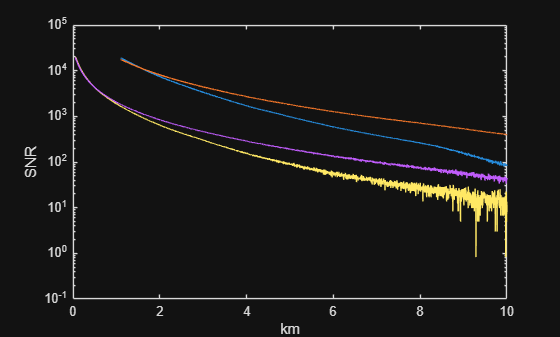

SNR_final = n_factor .* data_glued ./ sqrt(data_glued + solar_bg_full);

figure;
semilogy(hkm,SNR_final(:,1,id))
hold on
plot(hkm,SNR_final(:,2,id))
plot(hkm,SNR_final(:,3,id))
plot(hkm,SNR_final(:,4,id))

xlabel('km')
ylabel('SNR')
xlim([0 10])

Calculate air density

% standard atmosphere
[t,p,ND] = standard_atmosphere(hkm.*1e3);

Calculate differential molecular exctinction correction term

% On and off wavelengths
lam_on = 287.2; % nm
lam_off = 299.1; % nm

% Differential ozone absorption? cross section as function of temperature
ds_temp = load('.\auxiliary_data\dsigma_287d1_299d2_temperature_lookup.mat');
ds = interp1(ds_temp.dsigma_temp,ds_temp.dsigma,t);

% refractive index of air 
n = @(lam) 1 + (1e-8) * (6432.8 + 2949810/(146-lam.^-2) + 25540/(41-lam.^-2));

n_on = n(lam_on * 1e-3);
n_off = n(lam_off * 1e-3);

% scattering cross-section
rho = 0.035;
s = @ (lam, n, ND) ...
    (24 * pi^3) ./ (lam.^4 .* ND.^2) .* ...
    ((n.^2 - 1)./(n.^2 + 2)).^2 * ((6 + 3*rho)/(6 - 7*rho));

s_on = s(lam_on * 1e-9, n_on, ND(1));
s_off = s(lam_off * 1e-9, n_off, ND(1));

%  Molecular extinction profiles for on and off wavelengths
am_on = ND.*s_on;
am_off = ND.*s_off;

% Difference in molecular extinction correction
D_correction = ND.*(s_on - s_off) ./ ds; % check that calculation and units are correct
D_correction = repmat(D_correction, 1, n_profiles);

Calculate ozone number density

M1_fr = 11;
M2_fr = 321;
N1_fr = (M1_fr-1)/2;
N2_fr = (M2_fr-1)/2;

M1_nr = 11;
M2_nr = 53;
N1_nr = (M1_nr-1)/2;
N2_nr = (M2_nr-1)/2;

h1_fr = 1.2;
h2_fr = 10;

h1_nr = .2;
h2_nr = 1.2;

fl_fr = 2.*(round(((N2_fr-N1_fr)/(h2_fr-h1_fr)).*(hkm-h1_fr) + N1_fr))+1;
fl_fr(hkm < h1_fr) = M1_fr;
fl_fr(hkm > h2_fr) = M2_fr;

fl_nr = 2.*(round(((N2_nr-N1_nr)/(h2_nr-h1_nr)).*(hkm-h1_nr) + N1_nr))+1;
fl_nr(hkm < h1_nr) = M1_nr;
fl_nr(hkm > h2_nr) = M2_nr;

load('sg_filters.mat');

p_on_fr = squeeze(data_glued(:,1,:));
p_off_fr = squeeze(data_glued(:,2,:));
r_fr = p_on_fr./p_off_fr;
r_log_fr = log(r_fr);

p_on_nr = squeeze(data_glued(:,3,:));
p_off_nr = squeeze(data_glued(:,4,:));
r_nr = p_on_nr./p_off_nr;
r_log_nr = log(r_nr);

p_on_fr_sm = NaN(size(p_on_fr));
p_off_fr_sm = NaN(size(p_off_fr));

p_on_nr_sm = NaN(size(p_on_nr));
p_off_nr_sm = NaN(size(p_off_nr));

N_fr = NaN(size(p_on_fr));
N_nr = NaN(size(p_on_nr));

for i = 1:n_profiles
    for k = 1:length(p_on_fr)
        m = fl_fr(k);
        N = (m-1)/2;
    
        filt_smooth = sg_smooth{N};
        filt_diff = sg_diff{N};

        if k-N >= 1 && k+N <= n_bin
            p_on_fr_sm(k,i) = filt_smooth(N+1,:) * p_on_fr(k-N:k+N,i);
            p_off_fr_sm(k,i) = filt_smooth(N+1,:) * p_off_fr(k-N:k+N,i);

            N_fr(k,i) = filt_diff(:,2)' * r_log_fr(k-N:k+N,i) * (-1/(2*ds(k))) * (1/dzm);
        end
    end
end

for i = 1:n_profiles
    for k = 1:length(p_on_fr)
        m = fl_nr(k);
        N = (m-1)/2;

        filt_smooth = sg_smooth{N};
        filt_diff = sg_diff{N};

        if k-N >= 1 && k+N <= n_bin
            p_on_nr_sm(k,i) = filt_smooth(N+1,:) * p_on_nr(k-N:k+N,i);
            p_off_nr_sm(k,i) = filt_smooth(N+1,:) * p_off_nr(k-N:k+N,i);

            N_nr(k,i) = filt_diff(:,2)' * r_log_nr(k-N:k+N,i) * (-1/(2*ds(k))) * (1/dzm);
        end
    end
end

Plot comparing smoothed signal profile with pre-processed non-smoothed profile

shw_plt = false;
if shw_plt == true
    figure;
    semilogy(hkm,p_on_fr(:,id))
    hold on;
    plot(hkm,p_on_fr_sm(:,id),'--')
    xlabel('km')
    ylabel('')
    xlim([0 10])
    figure;
    imagesc(times_avg,hkm,p_on_fr)
    set(gca,'YDir','Normal')
    set(gca,'ColorScale','log')
    ylim([0 10])
    colorbar
    colormap('jet')
    figure;
    imagesc(times_avg,hkm,p_on_fr_sm)
    set(gca,'YDir','Normal')
    set(gca,'ColorScale','log')
    ylim([0 10])
    colorbar
    colormap('jet')
end

Plots of SG filter length as function of altitude for NR and FR 

shw_plt = false;
if shw_plt == true
    figure;
    hold on
    plot(hkm,fl_fr)
    plot(hkm,fl_nr)
    hold off
    legend(["FR" "NR"])
    xlabel('km')
    ylabel('SG filter length')
end

Merge ozone number density from FR and NR channels

start_merge = 1.2;
end_merge = 1.5;

merge_ind = find(hkm > start_merge & hkm < end_merge);
hkm_merge = hkm(merge_ind);

w = (hkm_merge - hkm_merge(1)) ./ (hkm_merge(end) - hkm_merge(1));

N_merge = w.*N_fr(merge_ind,:) + (1-w).*N_nr(merge_ind,:);

N_o3 = N_nr;
N_o3(merge_ind,:) = N_merge;
N_o3(hkm > end_merge,:) = N_fr(hkm > end_merge,:);

Plot of FR, NR, and FR-NR merged profiles

shw_plt = false;
if shw_plt == true
    figure;
    hold on;
    plot(N_fr(:,id),hkm)
    plot(N_nr(:,id),hkm)
    plot(N_o3(:,id),hkm)
    hold off;
    ylim([0 10])
    xlim([0 2*10^18])
    xlabel('O3 number density (1/m^3)')
    ylabel('km')
    legend(["FR" "NR" "merged"])
end

Calculate ozone mixing ratio

c_lim = [0 120];
y_lim = [0 10];

ND_a = repmat(ND, 1, n_profiles);

N_o3_corrected = N_o3 - D_correction;
O3_ppb = N_o3_corrected ./ ND_a * 10^9;

O3_ppb_cld = O3_ppb;
O3_ppb_cld(logical(squeeze(cld_mask(:,1,:)))) = NaN;


Plots of ozone number density

shw_plt = false;
if shw_plt == true
    ND_plot(times_avg,hkm,N_o3, [0 5e18],y_lim,"N_O3 uncorrected for differential scattering (1/m^3)")
    ND_plot(times_avg,hkm,N_o3_corrected, [0 5e18],y_lim,"N_O3 corrected for differential scattering (1/m^3)")
end

Plots of ozone mixing ratio

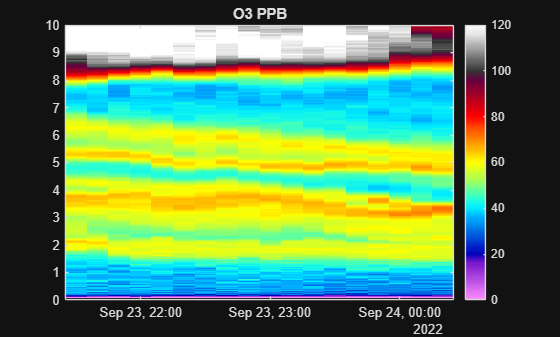

shw_plt = true;
if shw_plt == true
    ND_plot(times_avg, hkm, O3_ppb, c_lim,y_lim,"O3 PPB")
    % ND_plot(times_avg, hkm, O3_ppb_cld, c_lim,y_lim,"O3 PPB cloud screened")
end

Calculate Aerosol Correction Term

Sm = 8*pi/3; % Molecular extinction-to-backscatter-ratio(sr): 8*pi/3
Sa = 50; % Aerosol extinction-to-backscatter ratio (sr)
z_ref = 8000;
z_surf = 300;
ae = 1.5; % Angstrom Exponent, positive value, usually 1.5 for urban aerosol
Rc = 1.005;  % reference value for the total-backscatter to molecular backscatter ratio

bm_off = am_off ./ Sm; % the molecular backscatter at 299-nm [/sr/m]
sigma_o3_off = 4.551e-23;

bin_ref = round(z_ref/dzm);
start_bin = round(z_surf/dzm);

ba_ref = (Rc-1)*am_off(bin_ref)/Sa;
ba = NaN(size(p_off_fr_sm));
ba(bin_ref,:) = ba_ref;

aa = NaN(size(p_off_fr_sm));

aa(bin_ref,:) = Sa * ba(bin_ref,:); % will be for first iteration only
for i = 1:n_profiles
    % for k = 1:max_iter
        for j = bin_ref-1:-1:start_bin
    
            % Log ratio
            log_ratio = log(p_off_fr_sm(j,i) / p_off_fr_sm(j+1,i)); % need to remove negatives from signals - fillwithmissing
    
            % Geometry + backscatter
            range_factor = (height(j)/height(j+1))^2;
            bs_sum = bm_off(j+1) + ba(j+1);
            m1 = range_factor * bs_sum;
    
            % Final backscatter calculation
            ba(j,i) = max(exp(log_ratio - 2*sigma_o3_off*dzm*N_o3(j,i) - 2*dzm*(am_off(j+1) + aa(j+1))) * m1 - bm_off(j),0); % potentially add warning if large negatives appear
            % ba(j,i) = exp(log_ratio - 2*sigma_o3_off*dzm*N_o3(j,i) - 2*dzm*(am_off(j+1) + aa(j+1))) * m1 - bm_off(j);
            aa(j,i) = Sa * ba(j,i);
        end

        % break if stopping criteria reached
    % end
end

Plot of aerosol correction value

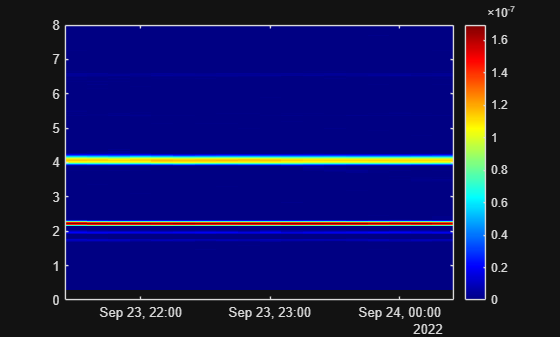

shw_plt = true;
if shw_plt == true
    figure;
    I = imagesc(times_avg,hkm,ba); % need to fix negatives in signal profile to fix complex values
    ax = gca;
    set(ax,'YDir','normal')
    % ax.CLim = [0 9e-7];
    colorbar
    colormap('jet')
    ylim([0 z_ref/1000])
    set(I,'AlphaData',~isnan(ba));
end

function profile_plot(id, data, hkm, times, an_title,pc_title)
    figure;
    semilogy(hkm,data(:,1,id),hkm,data(:,3,id),hkm,data(:,5,id),hkm,data(:,7,id))
    xlabel('distance')
    ylabel('mV')
    xlim([0 8])
    title([an_title  string(times(id))])
    legend(["287 nm FR" "299 nm FR" "287 nm NR" "299 nm FR"])

    figure;
    semilogy(hkm,data(:,2,id),hkm,data(:,4,id),hkm,data(:,6,id),hkm,data(:,8,id))
    xlabel('distance')
    ylabel('MHz')
    xlim([0 8])
    ylim([10^-4 10^4])
    title([pc_title  string(times(id))])
    legend(["287 nm FR" "299 nm FR" "287 nm NR" "299 nm FR"])
end

function b = scale_analog(an,pc)
    X = [ones(length(an),1) an];
    b = X\pc;
end

function [t, p, nd] = standard_atmosphere(z_m)
    t = NaN(size(z_m));
    p = NaN(size(z_m));
    
    g = 9.80665;
    M = 0.0289644;
    R = 8.3144598;
    NA = 6.02214076 * 10^23;
    
    for i = 1:length(z_m)
        zi = z_m(i);
    
        if zi >=0 && zi < 11
            T0 = 288.15;
            p0 = 101325;
            z0 = 0;
            L = -0.0065;
    
        elseif zi >= 11000 && zi < 20000
            T0 = 216.65;
            p0 = 22632.1;
            z0 = 11000;
            L = 0;
    
    
        elseif zi >= 20000 && zi < 32000
            T0 = 216.65;
            p0 = 5474.89;
            z0 = 20000;
            L = 0.001;
    
        elseif zi >= 32000 && zi < 47000
            T0 = 228.65;
            p0 = 868.019;
            z0 = 32000;
            L = 0.0028;
    
        elseif zi >= 47000 && zi < 51000
            T0 = 270.65;
            110.906;
            z0 = 47000;
            L = 0;
    
        elseif zi >= 51000 && zi < 71000
            T0 = 270.65;
            p0 = 66.9389;
            z0 = 51000;
            L = -0.0028;
    
        elseif zi >= 71000 && zi < 84852
            T0 = 214.65;
            p0 = 3.95642;
            z0 = 71000;
            L = -0.002;
    
        elseif zi > 84852
            T0 = 186.946;
            p0 = 0;
            z0 = 84852;
            L = 0;
    
        else
            %  error
        end
        
        t_temp = T0 + L * (zi - z0);
    
        if L == 0
            p(i) = p0 * exp(-g*M*(zi-z0)/(R*T0));
        else
            p(i) = p0 * (T0/t_temp).^(g*M/R/L);
        end
    
        t(i) = t_temp;
    end

    nd = p .* NA ./ (R .* t);
end

function ND_plot(x,y,z,c_lim,y_lim,title_str)
    figure;
    I = imagesc(x, y, z);
    cbar_tolnet=colorbar_tolnet_func;
    colormap(cbar_tolnet);
    ax = gca;
    ax.CLim = c_lim;
    set(gca,'YDir','normal');
    set(I,'AlphaData',~isnan(z));
    ylim(y_lim)
    colorbar
    title(title_str)
end